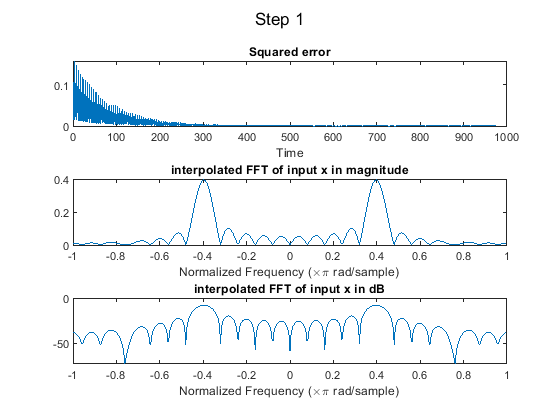

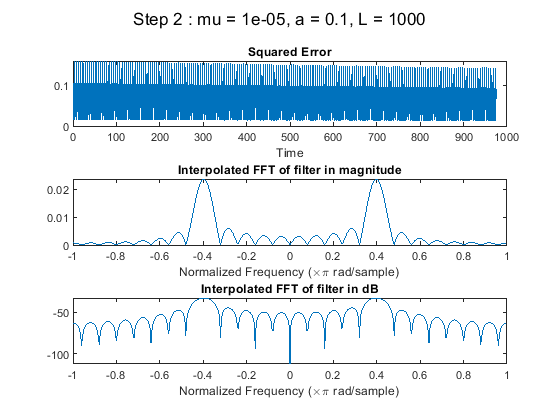

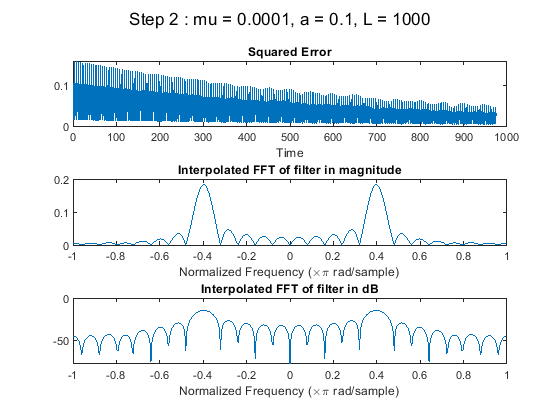

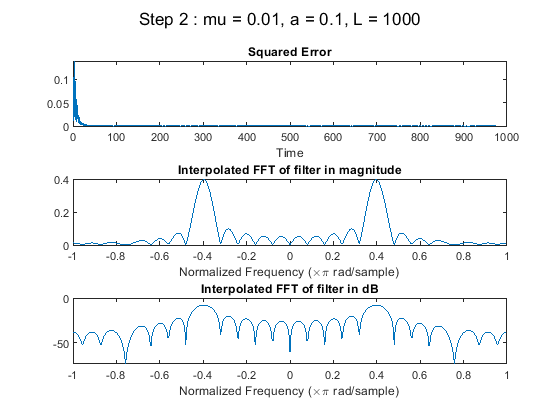

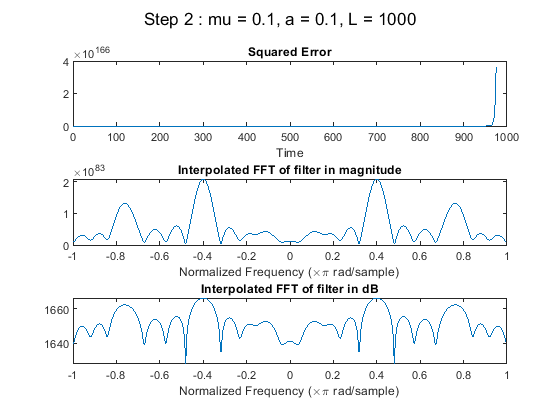

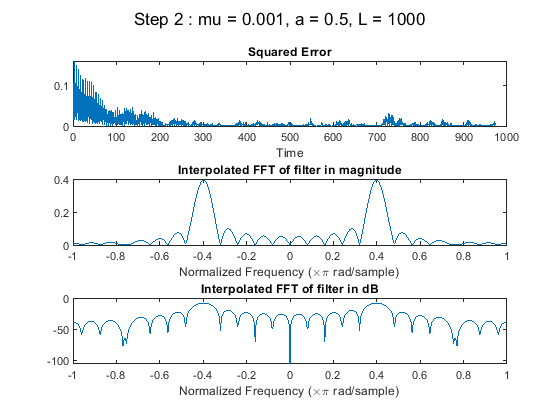

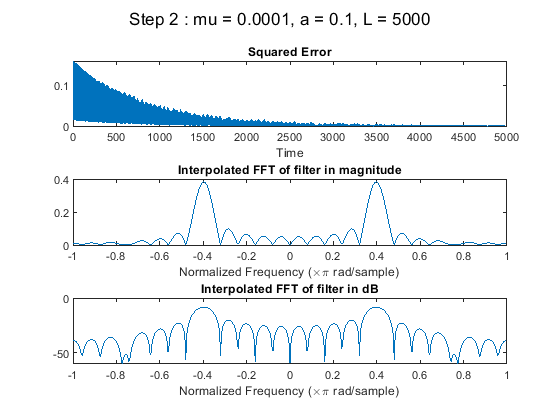

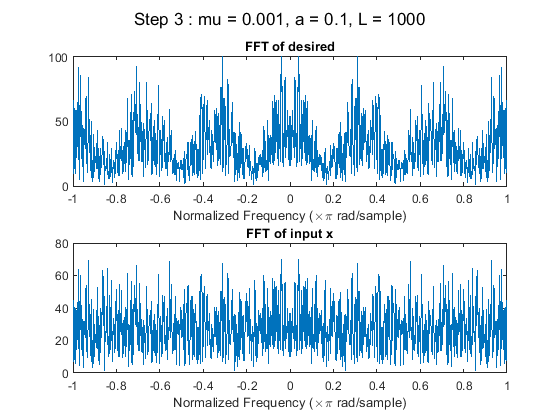

close all 

clear
clc

%% Step 1
M = 25;
L = 1000;
mu = 0.001;
a = 0.1;

w      = zeros(M,1);
yout   = zeros(M,1);
errout = zeros(M,1);

x = cos(2*pi*0.2*(0:(L-1))) + cos( 2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1)) + pi/5);

for n = 1:L-M
    xn = x(n:n+M-1)';
    yn = w'*xn;
    yout(n) = yn;
    en = d(n) - yn;
    errout(n) = en;
    w = w + mu * en * xn;

end
N  = L;
fv = (0:(N-1)) - floor(N/2);
fvM0 = (0:(512-1)) - floor(512/2);
fv = 2*fv/N;
fvM0 = 2*fvM0/512;

figure()
sgtitle('Step 1')
subplot(3,1,1)
plot(errout.*errout);
xlabel('Time')
title('Squared error')
subplot(3,1,2)
plot(fvM0, abs(fftshift(fft(w,512))));
xlabel('Normalized Frequency (\times\pi rad/sample)')
title('interpolated FFT of input x in magnitude')
subplot(3,1,3)
plot(fvM0, mag2db(abs(fftshift(fft(w,512)))));
xlabel('Normalized Frequency (\times\pi rad/sample)')
title('interpolated FFT of input x in dB')

%{
Plot the interpolated fft of the filter w both in magnitude and dB. Compare this result to the least squares
filter result from the prelab.


%} 

%% Step 2
i = 0;
for mu = [0.00001 0.0001 0.01 0.1 0.001 0.0001]
    M = 25;
    L = 1000;
    a = 0.1;
    
    if i == 4
        a = 0.5;
    end    
    
    if i == 5
        L = 5000;
        a = 0.1;
    end
    
    w      = zeros(M,1);
    yout   = zeros(M,1);
    errout = zeros(M,1);
    
    x = cos(2*pi*0.2*(0:(L-1))) + cos( 2*pi*0.38*(0:(L-1)))+a*randn(1,L);  % this is x
    d = 0.4*cos(2*pi*0.2*(0:(L-1)) + pi/5);   % this is d
    
    for n = 1:L-M
        xn = x(n:n+M-1)';
        yn = w'*xn;
        yout(n) = yn;
        en = d(n) - yn;
        errout(n) = en;
        w = w + mu * en * xn;
    end
    
    N  = L;
    fv = (0:(N-1)) - floor(N/2);
    fv = 2*fv/N;
    fvM0 = (0:(512-1)) - floor(512/2);
    fvM0 = 2*fvM0/512;
    
    figure()
    sgtitle("Step 2 : mu = " + mu + ", a = " + a + ", L = " + L)
    subplot(3,1,1)
    plot(errout.*errout);
    xlabel('Time')
    title('Squared Error')
    subplot(3,1,2)
    plot(fvM0, abs(fftshift(fft(w,512))));
    xlabel('Normalized Frequency (\times\pi rad/sample)')
    title('Interpolated FFT of filter in magnitude')
    subplot(3,1,3)
    plot(fvM0, mag2db(abs(fftshift(fft(w,512)))));
    xlabel('Normalized Frequency (\times\pi rad/sample)')
    title('Interpolated FFT of filter in dB')
    i = i+1;
end 

%{ 
What is the lowest value of the error? If the error goes to close to zero, how many iterations does it take?
How much does the shape of the fft of the filter look like the least squares filter fft from the prelab?
What is the maximum value of the fft magnitude? How does that compare to the least squares fft from the
prelab?
Change noise level from 0.1 to 0.5
How do these results compare to Step 1 results? Why do you think the squared error curve is different?
Change input signal duration from 1000 to 5000 samples
Compare the results to the result earlier in this step which had the same value of mu and a, but had L =
1000.
%}
%% Step 3
M  = 25;
L  = 1000;
a  = 0.1;
i  = 0;
N  = L;

fv = (0:(N-1)) - floor(N/2);
fv = 2*fv/N;

fvM0 = (0:(512-1)) - floor(512/2);
fvM0 = 2*fvM0/512;

for mu = [0.001 0.01 0.05 0.08 0.0001 0.01]
    x = randn(1,L);  % this is x
    h = [1 0 0 0 0 0 0.5];
    xUnk = conv(h,x);
    d = xUnk(1:end - length(h)+1);
    
    if i == 5
        d = xUnk(length(h):end);
    end
    
    for n = 1 : L-M
        xn = x(n:n+M-1)';
        yn = w'*xn;
        yout(n) = yn;
        en = d(n) - yn;
        errout(n) = en;
        w = w + mu * en * xn;
    end
        
    if i == 0
        figure()
        sgtitle("Step 3 : mu = " + mu + ", a = " + a + ", L = " + L)
        subplot(2,1,1)
        plot(fv, abs(fftshift(fft(d,L))));
        xlabel('Normalized Frequency (\times\pi rad/sample)')
        title('FFT of desired')

        subplot(2,1,2)
        plot(fv, abs(fftshift(fft(x,L))));
        xlabel('Normalized Frequency (\times\pi rad/sample)')
         title('FFT of input x')
        
    else
        figure()
        sgtitle("Step 3 : mu = " + mu + ", a = " + a + ", L = " + L)
        subplot(3,2,1)
        plot(fv, abs(fftshift(fft(d))));
        xlabel('Normalized Frequency (\times\pi rad/sample)')
        title('FFT of desired')

        subplot(3,2,2)
        plot(fv, abs(fftshift(fft(x))));
        xlabel('Normalized Frequency (\times\pi rad/sample)')
        title('FFT of input x')

        subplot(3,2,3)
        plot(errout.*errout);
        xlabel('Time')
        title('Squared error with mu = 0.01' )

        subplot(3,2,4)
        stem(w);
        title('Stem plot')

        subplot(3,2,5)
        plot(fvM0, abs(fftshift(fft(w,512))));
        xlabel('Normalized Frequency (\times\pi rad/sample)')
        title('Interpolated FFT of filter in magnitude')

        subplot(3,2,6)
        plot(fvM0, mag2db(abs(fftshift(fft(w,512)))));
        xlabel('Normalized Frequency (\times\pi rad/sample)')
        title('Interpolated FFT of filter in dB')
    end
    i = i + 1;
end
%{
Compare the filter w with the unknown filter h. How similar is it?
What is the error level at the end of the adaptation loop?

Rerun the filter with mu = 0.01 and compare.
Describe the results you obtain with mu = 0.05, 0.08, and 0.0001.
Explore the importance of timing alignment: Describe the output and explain.

%}
%% Step 4
M  = 25;
L  = 1000;
a  = 0.1;
i  = 0;
mu = 0.01;
N  = L;
fv = (0:(N-1)) - floor(N/2);
fv = 2*fv/N;
fvM0 = (0:(512-1)) - floor(512/2);
fvM0 = 2*fvM0/512;

for n = 1:2
    f_pm = [0, 1200, 1600, 2400, 2800, 4000]/4000;
    a_pm = [0,0,1,1,0,0]; % band pass
    n_pm = 64;
    b_pm = firpm(n_pm, f_pm, a_pm);
    x = randn(1,L); % create x input for both filters
    x_unk = conv(b_pm, x);
    d = x_unk(1: end- length(b_pm)+1); % make d the same length as x
    
    if n == 2
        n_pm = 32;
    end
    
    h = [1 0 0 0 0 0 0.5];
    xUnk = conv(h,x);
    
    for n = 1 : L-M
        xn = x(n:n+M-1)';
        yn = w'*xn;
        yout(n) = yn;
        en = d(n) - yn;
        errout(n) = en;
        w = w + mu * en * xn;
    end
    
    figure()
    sgtitle("Step 4 : mu = " + mu + ", n_pm = " + n_pm)
    subplot(3,2,1)
    plot(fv, abs(fftshift(fft(d))));
    xlabel('Normalized Frequency (\times\pi rad/sample)')
    title('FFT of desired')

    subplot(3,2,2)
    plot(fv, abs(fftshift(fft(x))));
    xlabel('Normalized Frequency (\times\pi rad/sample)')
    title('FFT of input x')

    subplot(3,2,3)
    plot(errout.*errout);
    xlabel('Time')
    title('Squared error with mu = 0.01' )

    subplot(3,2,4)
    stem(w);
    title('Stem plot')

    subplot(3,2,5)
    plot(fvM0, abs(fftshift(fft(w,512))));
    xlabel('Normalized Frequency (\times\pi rad/sample)')
    title('Interpolated FFT of filter in magnitude')

    subplot(3,2,6)
    plot(fvM0, mag2db(abs(fftshift(fft(w,512)))));
    xlabel('Normalized Frequency (\times\pi rad/sample)')
    title('Interpolated FFT of filter in dB')

    i = i + 1;
end

%{
Does the error get reduced as the filter adapts? Try a few other values for mu and see if there is any
improvement. Why is this filter not working well?

Explain why this change of n_pm made an improvement compared to the previous result. What other
change might have improved the result?
%}
